load('S01.mat')


trigger=data{1,1}.trial %start and stop signal 

trigger = 12×1 uint32 column vector
    238
    360
    639
    760
   1039
   1160
   1439
   1560
   1839
   1960
   2239
   2360


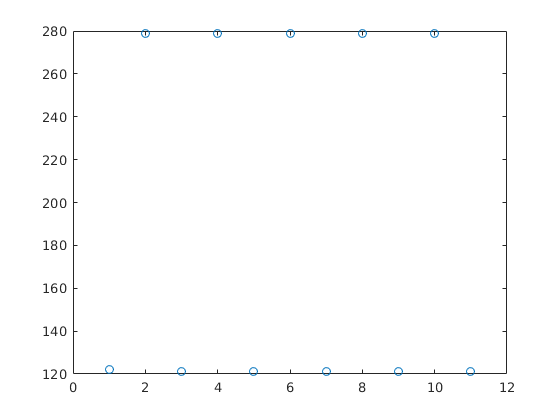

plot(diff(trigger),"o")

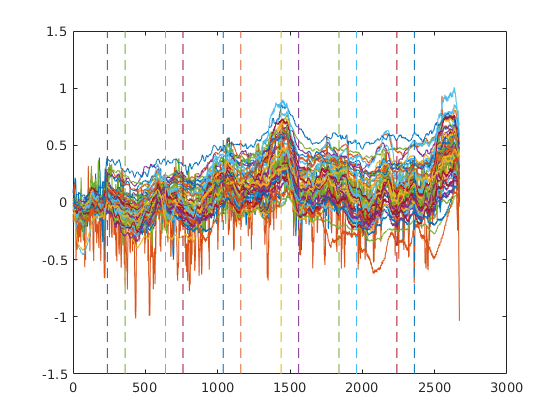

oxy=data{1,1}.X(:,1:52);
plot(oxy)
hold on
for l=trigger
    plot([l,l],[-1.5,1.5],"--")
end
hold off

Compute cusum

N=length(oxy(:,1))

N =         2671


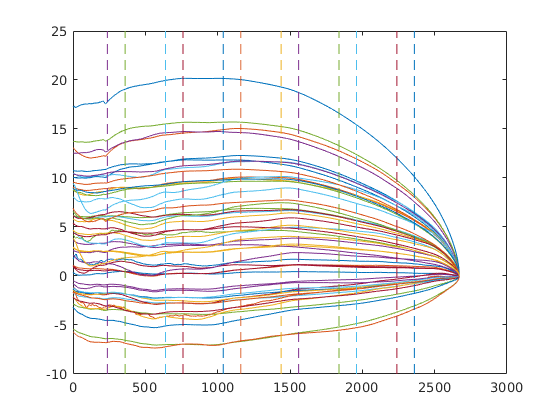

cusum_2nd=flipud(cumsum(flipud(oxy)));
t1=1:N-1;
cusum_1st=sqrt((N-1-t1)./((N-1)*t1))'.*cumsum(oxy(1:end-1,:));
t2=1:N-1;
cusum_2nd=cusum_2nd(2:end,:)*sqrt(t2/((N-t2)*N));
cusum=cusum_1st+cusum_2nd;
figure()
plot(cusum)


hold on
for l=trigger
    plot([l,l],[-10,25],"--")% it is the plot of vertical lines
end
hold off

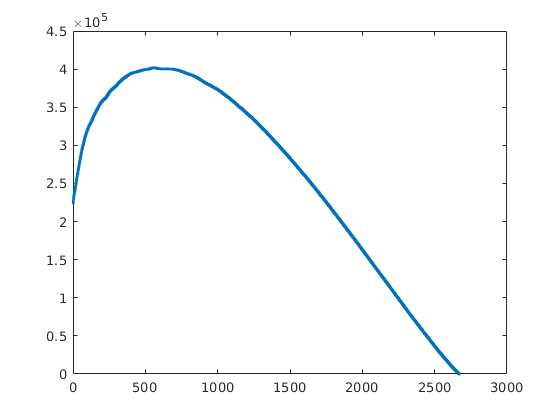

plot(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'),".")

[M,k]=max(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'))

M =    4.0171e+05


k =    563


[cusum, idx]=my_cusum(oxy);

N =         2671


M =    4.0171e+05


k =    563


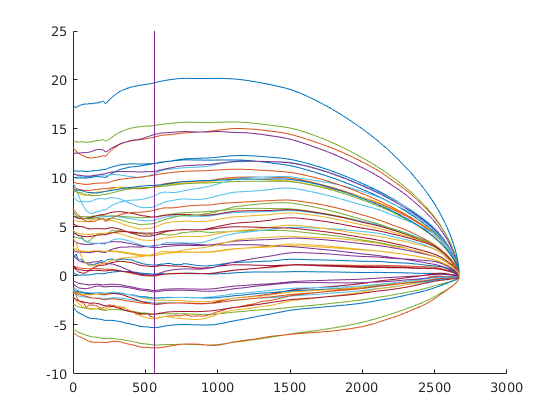

figure()
hold on
plot(cusum)
plot([idx,idx],[-10 25])
hold off